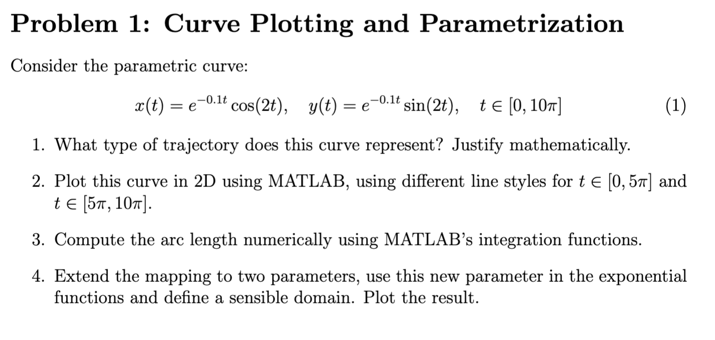

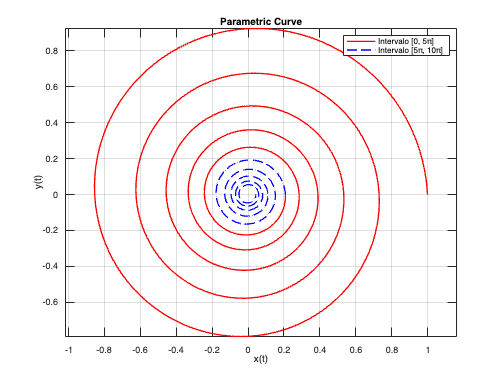

% Problem 1: Curve Plotting and Parametrization

% Parte 1: Identificar el tipo de trayectoria
% La curva es una espiral que se contrae hacia el origen debido al factor
% exponencial e^(-0.1t), mientras que cos(2t) y sin(2t) generan un
% movimiento circular.

% Parte 2: Graficar la curva en 2D
t1 = linspace(0, 5*pi, 500); % Intervalo [0, 5π]
t2 = linspace(5*pi, 10*pi, 500); % Intervalo [5π, 10π]

% Definición de la curva
x1 = exp(-0.1*t1) .* cos(2*t1);
y1 = exp(-0.1*t1) .* sin(2*t1);

x2 = exp(-0.1*t2) .* cos(2*t2);
y2 = exp(-0.1*t2) .* sin(2*t2);

% Graficar
figure;
plot(x1, y1, 'r-', 'LineWidth', 1.5); % Línea roja para [0, 5π]
hold on;
plot(x2, y2, 'b--', 'LineWidth', 1.5); % Línea azul punteada para [5π, 10π]
xlabel('x(t)');
ylabel('y(t)');
title('Parametric Curve');
legend('Intervalo [0, 5π]', 'Intervalo [5π, 10π]');
grid on;
axis equal;


% Parte 3: Calcular la longitud del arco numéricamente
% Derivadas de x(t) y y(t)
dx_dt = @(t) -0.1*exp(-0.1*t).*cos(2*t) - 2*exp(-0.1*t).*sin(2*t);
dy_dt = @(t) -0.1*exp(-0.1*t).*sin(2*t) + 2*exp(-0.1*t).*cos(2*t);

% Longitud del arco para t en [0, 10π]
arc_length = integral(@(t) sqrt(dx_dt(t).^2 + dy_dt(t).^2), 0, 10*pi);

fprintf('La longitud del arco es: %.4f\n', arc_length);

La longitud del arco es: 19.1596


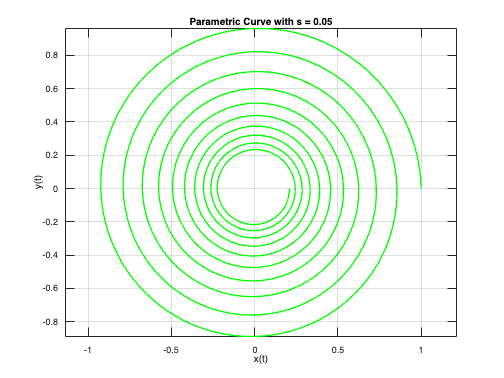


% Parte 4: Extender el mapeo a dos parámetros
s = 0.05; % Nuevo parámetro
t = linspace(0, 10*pi, 1000);

% Nueva parametrización con s
x_new = exp(-s*t) .* cos(2*t);
y_new = exp(-s*t) .* sin(2*t);

% Graficar la nueva parametrización
figure;
plot(x_new, y_new, 'g-', 'LineWidth', 1.5); % Línea verde para la nueva parametrización
xlabel('x(t)');
ylabel('y(t)');
title(['Parametric Curve with s = ', num2str(s)]);
grid on;
axis equal;